% ------------------------------ BEGIN CODE -------------------------------

disp("BENCHMARK: TORA Heterogeneous (tanh)")

BENCHMARK: TORA Heterogeneous (tanh)



% Parameters --------------------------------------------------------------
R0 = interval([-0.57;-0.25;0.31;-0.3],[-0.55;-0.23;0.34;-0.28]);

params.tFinal = 5.2;
params.R0 = polyZonotope(R0);

% Reachability Settings ---------------------------------------------------

options.timeStep = 0.05;
options.alg = 'lin';
options.tensorOrder = 3;
options.taylorTerms = 4;
options.zonotopeOrder = 200;
options.errorOrder = 10;
options.intermediateOrder = 50;

% Parameters for NN evaluation --------------------------------------------

evParams = struct();
evParams.poly_method = "singh";

% System Dynamics ---------------------------------------------------------

% open-loop system
f = @(x,u) [x(2); -x(1) + 0.1*sin(x(3)); x(4); u(1) * 11];
sys = nonlinearSys(f);

% load neural network controller

nn = neuralNetwork.readONNXNetwork('/Users/rayenmhadhbi/PycharmProjects/nn_verification/TORA/cora/actor_model_tora_second_network_second_reward_fixed_state16.onnx');

% construct neural network controlled system
sys = neurNetContrSys(sys, nn, 0.5);

% Specification -----------------------------------------------------------

goalSet = interval([-0.2;-1;-0.6;-2.3], [0.2;-0.5;0.6;2.4]);
spec = specification(goalSet, 'safeSet', interval(params.tFinal));
% Verification ------------------------------------------------------------

t = tic;
[res, R, simRes] = verify(sys, spec, params, options, evParams, true);

Time to compute random simulations: 0.75852
Time to check violation in simulations: 0.41875
Time to compute reachable set: 5.9762
Time to check verification: 0.05474
Total Time: 7.2082


%R = reach(sys, params, options, evParams, spec);
tTotal = toc(t);
disp(['Result: ' res])

Result: VERIFIED



% Visualization -----------------------------------------------------------

disp("Plotting..")

Plotting..


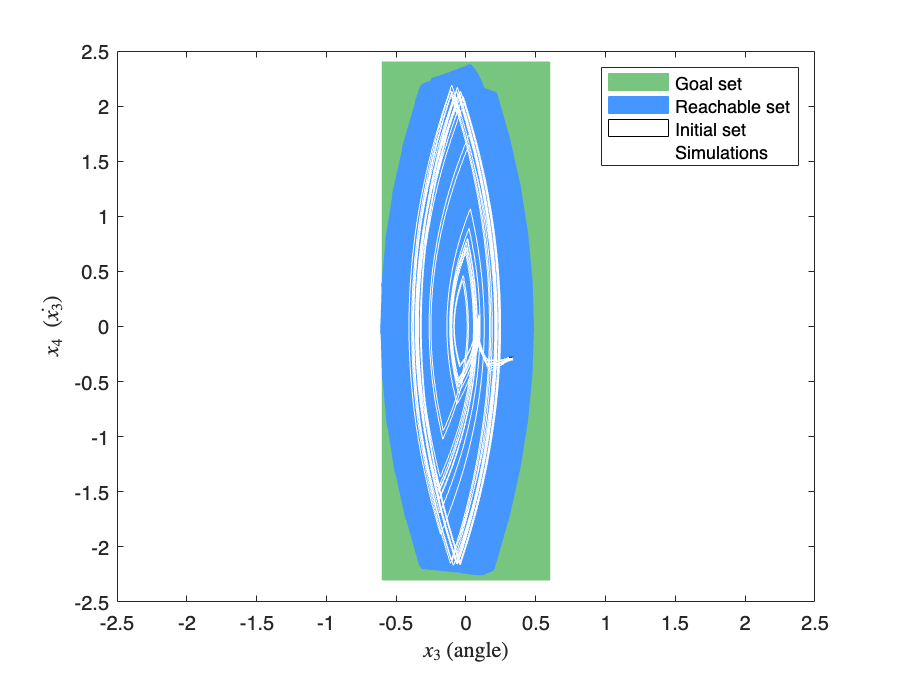

figure; hold on; box on;
projDims = [3, 4];

% plot specifications
plot(spec, projDims, 'DisplayName', 'Goal set');

% plot reachable set
useCORAcolors("CORA:contDynamics")
 plot(R, projDims, 'DisplayName', 'Reachable set');

% plot initial set
plot(R(1).R0, projDims, 'DisplayName', 'Initial set');

% plot simulations
plot(simRes, projDims, 'DisplayName', 'Simulations');

% labels, limits, and legend
xlabel('$x_3$ (angle)', 'interpreter', 'latex');
ylabel('$x_4\ (\dot{x_3})$', 'interpreter', 'latex')
xlim([-2.5, 2.5]);
ylim([-2.5, 2.5]);
legend()